# `Loop, functions, and .m files:`

- `for`` loop is used when no. of repetitions are known in advance.`

`    for`` variable = m:s:n`

`        statements(s) `

`    end`

`    where,   `

- `m: initial value`

- `s: step(incremental) value, (if not specified, it defaults to 1)`

- `n: final(terminating) value `

`Example 1`

`Find the following Taylor Series approximation:`

            
$$\sin {\left(x\right)}=x-\frac{x^3 }{3!}+\frac{x^5 }{3!}-\ldots+{\left(-1\right)}^n \frac{x^{2n+1} }{\left(2n+1\right)!}$$


x = pi/3;
n = 1:5; 
Y = zeros(size(n));
E = zeros(size(n));

for i = 0:2
    disp(i)
end

     0

     1

     2



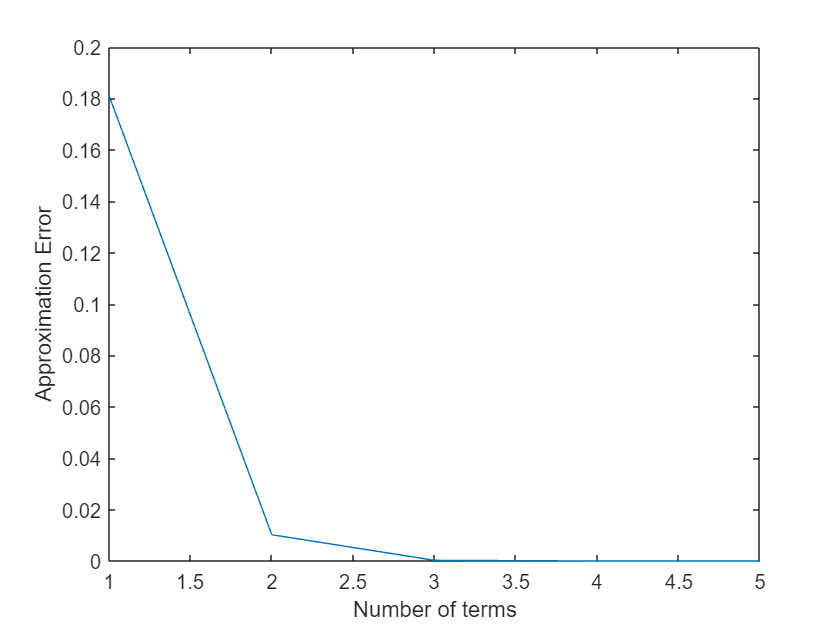

for i = 1:length(n)
    [E(i),Y(i)] = approx_sin(x,n(i));
end

plot(n,E)
ylabel('Approximation Error')
xlabel('Number of terms')

% SYmbolic Representation
syms a
num = 1;
[error1, approx1] = approx_sin(a,num)

$$error1 = \left|\sin\left(a\right)-a\right|$$

$$approx1 = a$$

% Anonymous Functions
approx_sin3 = @(x, num) sum(arrayfun(@(j) ((-1)^j * x^(2*j+1)) / factorial(2*j+1), 0:num-1));

x = pi/4;
num = 5;
approx2 = approx_sin3(x, num);
error2 = abs(approx2 - sin(x));
disp(['Approximation: ', num2str(approx2)]);

Approximation: 0.70711


disp(['Absolute error: ', num2str(error2)]);

Absolute error: 1.7503e-09


% disp

% sprintf
x = 10;
y = 3.14159;
formatted_string = sprintf('Integer: %d, Floating-point: %.2f', x, y);
disp(formatted_string);

## `Display:`

#### `format specifiers`

- `%d:`` Decimal notation for integers.`

- `%f:`` Fixed-point notation for floating-point numbers.`

- `%e: ``Exponential notation for large numbers`

- `%s: ``String/Character.`

% Define variables
integer = 123;

Integer: 10, Floating-point: 3.14


float = 3.14159;
exp = 123456789;
string = 'hello';

% Print using different format specifiers
fprintf('Integer (decimal): %d\n', integer);  % Decimal notation: 123
fprintf('Floating-point (fixed): %f\n', float);  % Fixed-point notation: 3.141590
fprintf('Exponential: %e\n', exp);  % Exponential notation: 1.234568e+08
fprintf('String: %s\n', string);  % String: hello


% select the block of code and press ctrl + shift + R to un-comment


Integer (decimal): 123


%function [error, approx] = approx_sin(x, num)

Floating-point (fixed): 3.141590


%     approx = 0;

Exponential: 1.234568e+08


%     for j = 0:num

String: hello


%         approx = approx + ((-1)^j* x^(2*j+1))/factorial(2*j+1);       
%     end
%     error = abs(approx - sin(x));
% end
% 
% function isEven(number)
%     if number == 0 
%         fprintf('Input should be Non-Zero')
% 
%     elseif mod(number, 2) == 0
%         fprintf('Given number %d is even',number)
% 
%     else
%         fprintf('Given number %d is odd',number)
%     end
% end

# `Norms, EVD, and SVD:`

The **p**-norm (or the $l_{\mathbf{p}}$-norm) of a vector $x\in \ {\mathit{\mathbf{R}}}^N$ is defined as


$${\left\|x\right\|}_p =\ {{\left(\sum_{i=1}^N {\left|x\right|}^p \right)}}^{\frac{1}{p}}$$


`n = norm(X,p) returns the p-norm of matrix X, where p is 1, 2, or Inf:`

- `If p = 1, then n is the maximum absolute column sum of the matrix.`

- `If p = 2, then n is approximately max(svd(X)). This value is equivalent to norm(X).`

- `If p = Inf, then n is the maximum absolute row sum of the matrix`

a_vec = [1;2;3;4].'

a_vec =      1     2     3     4


n1 = norm(a_vec,1)

n1 = 10

n2 = norm(a_vec,2)

n2 = 5.4772

ninf = norm(a_vec,'Inf')

ninf = 4

A = [1 2 3; 4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


A1 = norm(A,1)

A1 = 18

A2 = norm(A, 2)

A2 = 16.8481

Ainf = norm(A,'Inf')

Ainf = 24

Afro = norm(A, 'fro')

Afro = 16.8819

load('X_noise_Free.mat')
size(X)

ans =    100     6


size(X'*X)

ans =      6     6


[V, D] = eig(X'*X);

disp('Eigenvalues:');

Eigenvalues:


disp(diag(D));

   -0.0000
   -0.0000
   83.2428
  108.8330
  355.5248
  634.9315



disp('Eigenvectors:');

Eigenvectors:


disp(V);

    0.4633   -0.2274   -0.4886   -0.5123    0.4665   -0.1221
    0.3065    0.1364    0.8046   -0.4302    0.1736    0.1577
    0.4321   -0.4580    0.2444    0.6557    0.2712   -0.2007
   -0.4281   -0.7324    0.2060   -0.3341   -0.1653   -0.3147
   -0.3601    0.3816    0.1084    0.0430    0.5334   -0.6532
   -0.4379   -0.1949   -0.0030    0.0953    0.6057    0.6280



% SVD noise free data
[U, S, V] = svd(X);
diag(S)

ans =    25.1978
   18.8554
   10.4323
    9.1237
    0.0000
    0.0000


Xhat = (U(:,1:4)*S(1:4,1:4)*V(:,1:4)');
norm(X-Xhat,2) % induced 2-norm of the matrix

ans = 2.2695e-14

## `Noise generation`

### `SNR(or signal to noise ratio) = Variance of signal / Variance of noise ( Var(X)/Var(ek), X_noise = X + ek )`

load('X_noisy.mat')
% SVD noisy data
[Uz, Sz, Vz] = svd(Z);
diag(Sz)

ans =    25.4154
   19.5972
   11.3035
    9.9444
    4.1291
    3.7717


Zhat = (Uz(:,1:4)*Sz(1:4,1:4)*Vz(:,1:4)');
norm(Z-Zhat,2) % induced 2-norm of the matrix

ans = 4.1291

## `Image Compression application`

% reading the image from the folder and assign it to variable 
A=imread('VK.JPG');
% getting the size of the image as a matrix
V = size(A)

V =         2560        2560           3


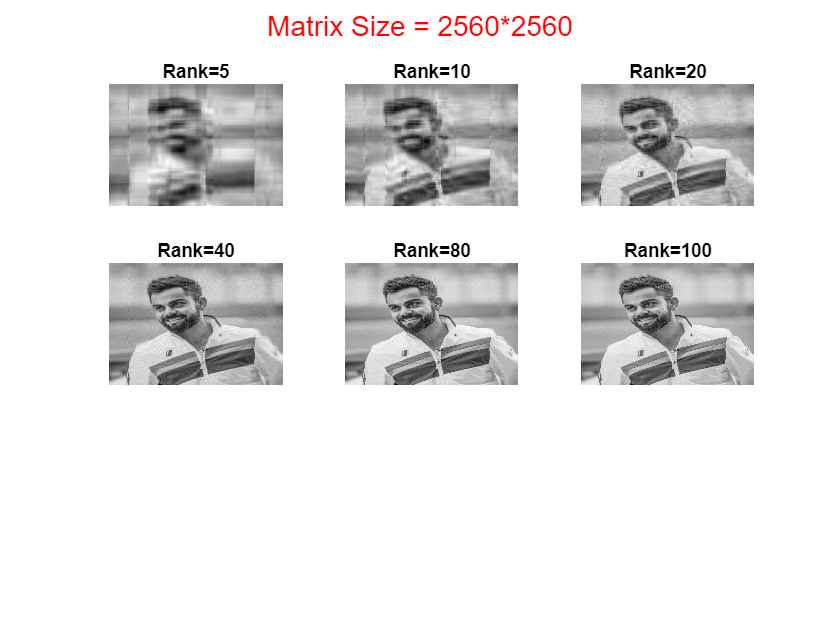

% changing the color of the image to gray scal for easier optomization
X=double(rgb2gray(A)); 
%length of x-axis as colum
nx = size(X,1);
%length of y-axis as row
ny = size(X,2);

imagesc(X), axis off, colormap gray
%calculating the econ SVD of the image matrix
[U,S,V] = svd(X,'econ');
plotind = 1;
 
% looping with R: 5 , 10 , 20 , 40 , 80 and 100
%and generate an image output as per its rank
 for r=[5 10 20 40 80 100]
     Xapprox = U(:,1:r)*S(1:r,1:r)*V(:,1:r)';
     subplot(3,3,plotind)
     plotind = plotind+1;
     imagesc(Xapprox), axis off , colormap gray
     title(['Rank=',num2str(r,'%d'),'']);
     
 end

 %setting the form title as the image matrix size X*Y
sgtitle(['Matrix Size = ',num2str(nx,' %d* '),num2str(ny,' %d '),''],'Color','red','FontSize',14)

a = [1,2; 2,4]

sum(a)